# Simulation Summary for Gaussian Copula Method

## Load Simulation Result Object

clear all
load('Gaussian_Copula9.mat')

## Degree of Freedom

MCMC chain of DOF

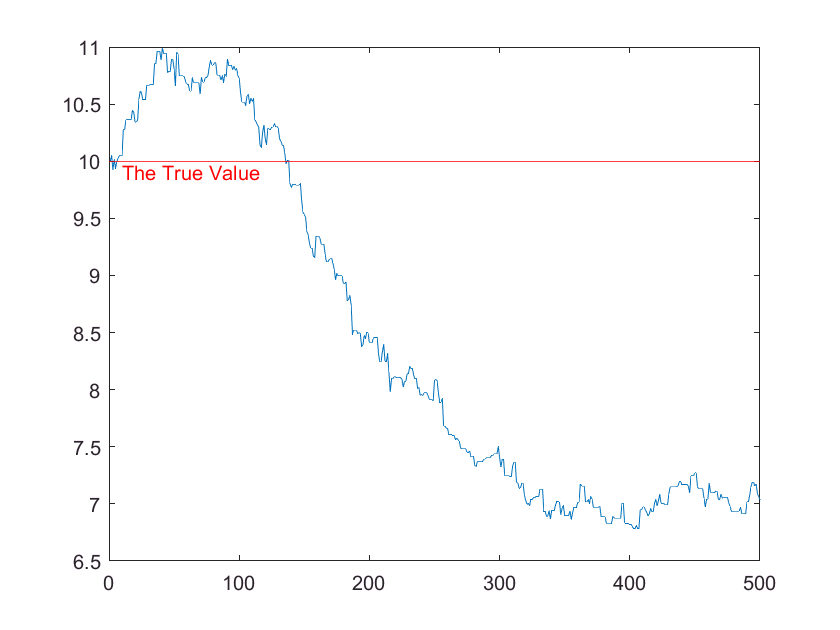

dof_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    dof_curr=obj{1};
   dof_all=[dof_all dof_curr('dof')];
end
plot(dof_all)
h = hline(dof,'r','The True Value');

Posterior Density of DOF

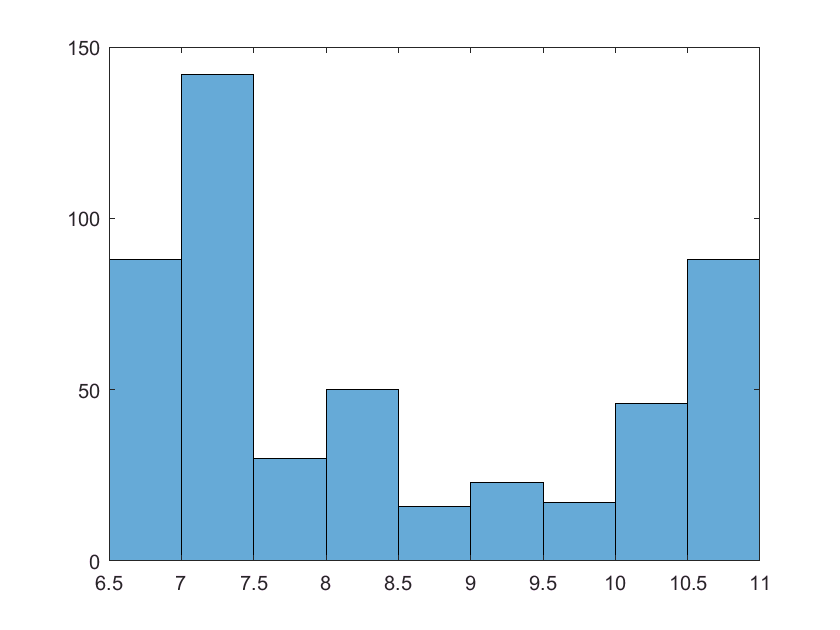

histogram(dof_all)

## Spatial Sill ($$\sigma_w^2$$) of Gaussian Process

MCMC of $$\sigma_w^2$$

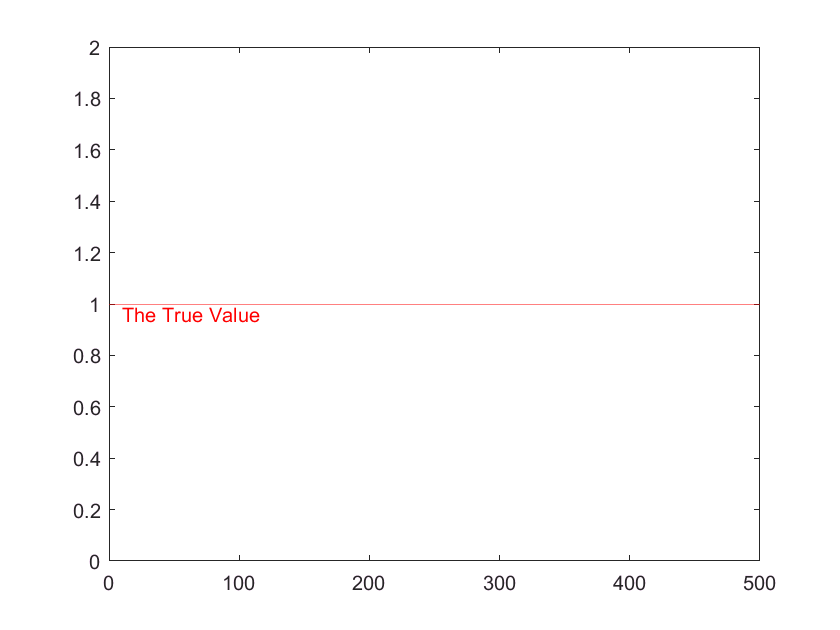

sigma_w_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    sigma_w_curr=obj{2};
   sigma_w_all=[sigma_w_all sigma_w_curr('sigma_w')];
end
plot(sigma_w_all)
h =hline(sigma_w,'r','The True Value');

Posterior Density of $$\sigma_w^2$$

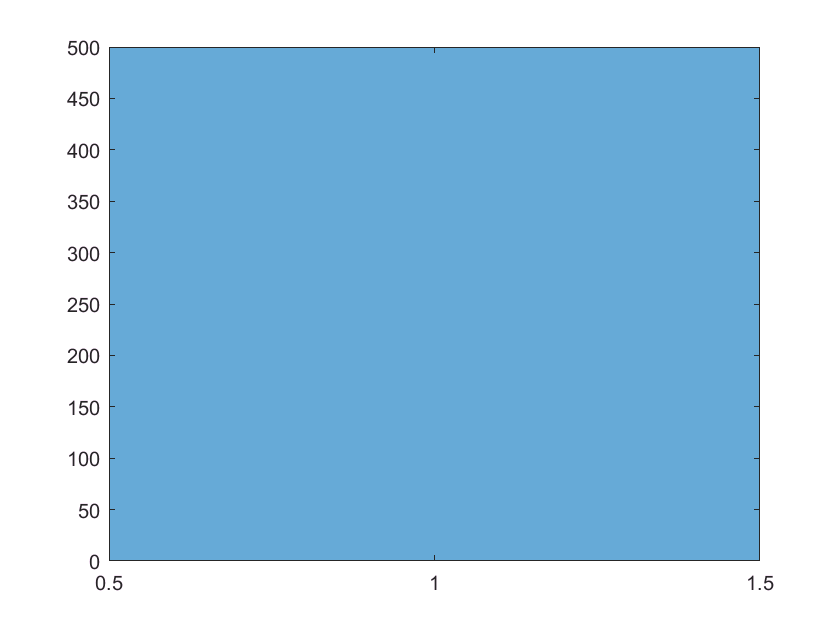

histogram(sigma_w_all)

## Spatial range ($\rho_w$) of Gaussian Process

MCMC of $\rho_w$

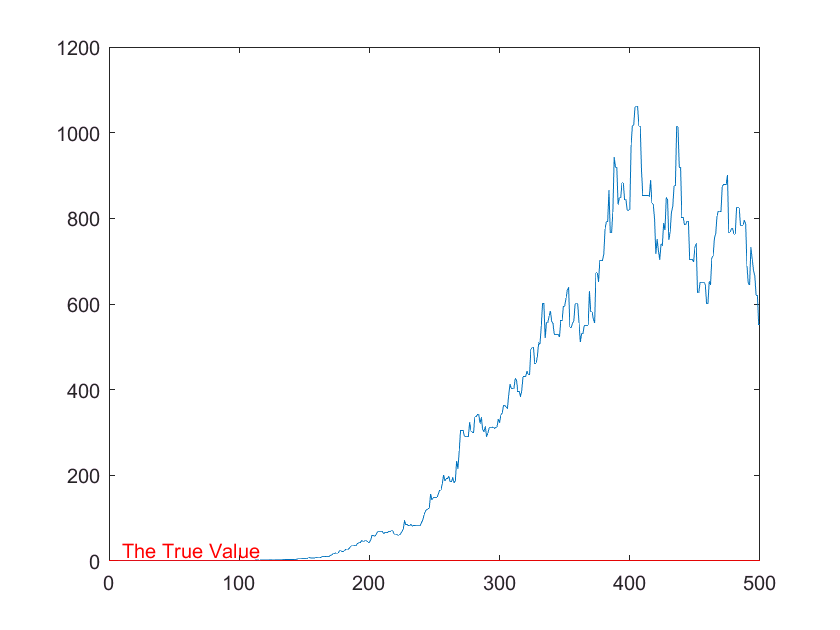

rho_w_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    rho_w_curr=obj{2};
   rho_w_all=[rho_w_all rho_w_curr('rho_w')];
end
plot(rho_w_all)
h =hline(rho_w,'r','The True Value');

Posterior Density of $\rho_w$

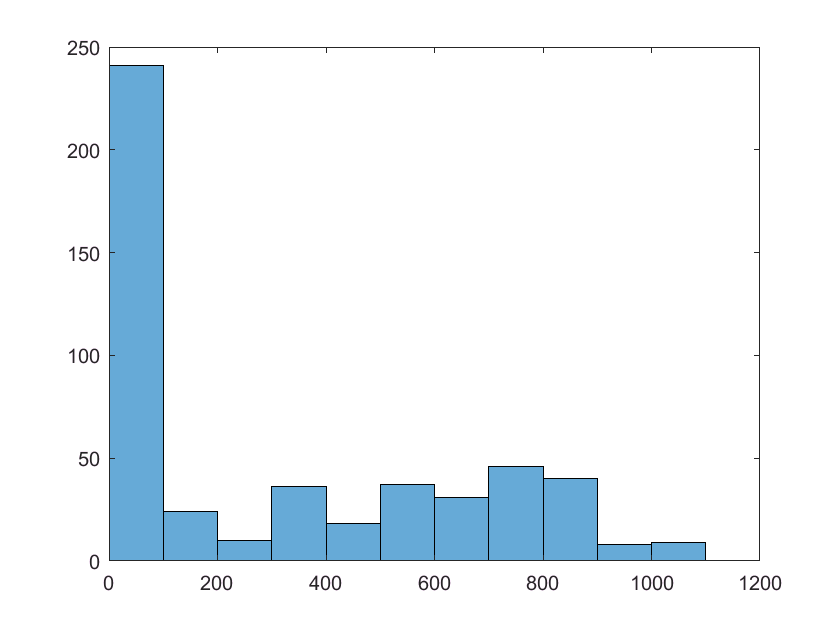

histogram(rho_w_all)

## Spatial DOF ($\nu_w$) of Gaussian Process

MCMC of $\nu_w$

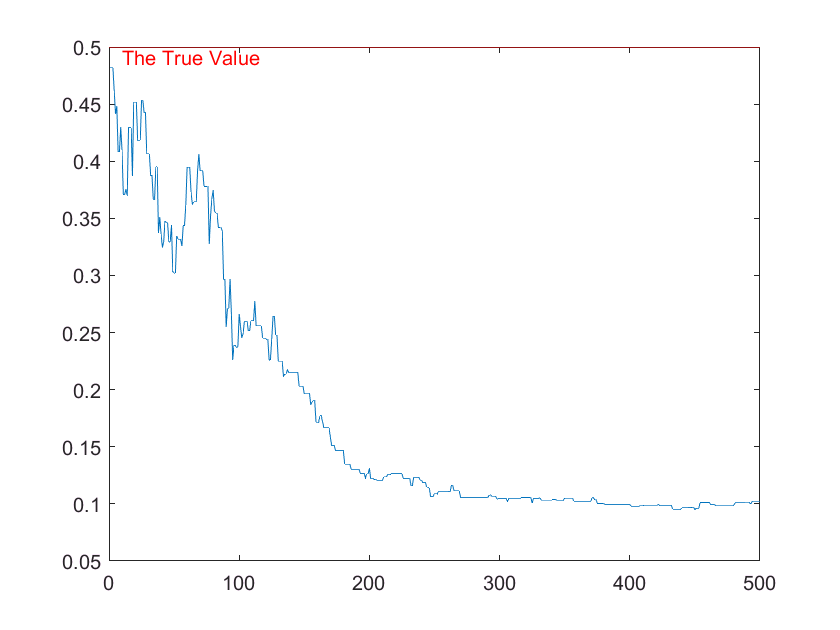

nu_w_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    nu_w_curr=obj{2};
   nu_w_all=[nu_w_all nu_w_curr('nu_w')];
end
plot(nu_w_all)
h =hline(nu_w,'r','The True Value');

Posterior Density of $\nu_w$

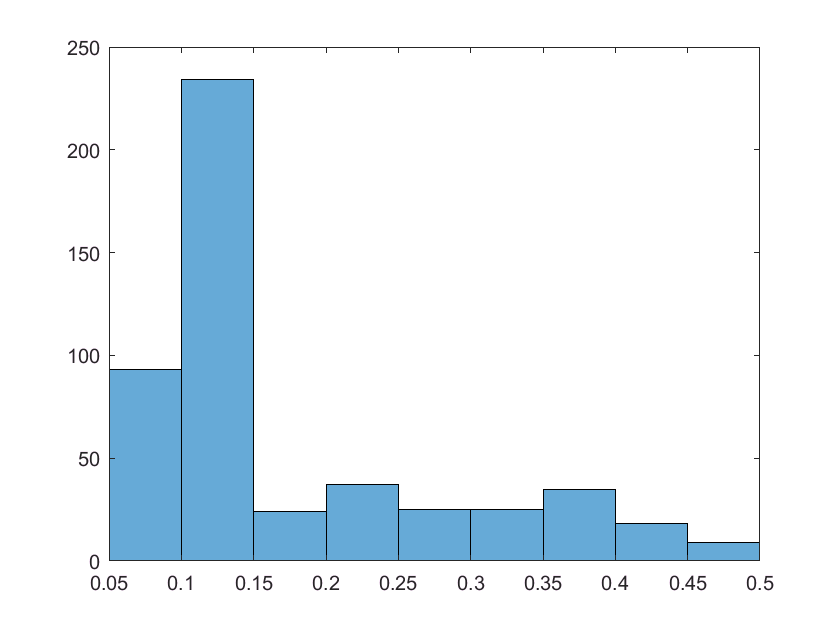

histogram(nu_w_all)

## Spatial range ($\rho_c$) of Gaussian Copula

MCMC of $\rho_c$

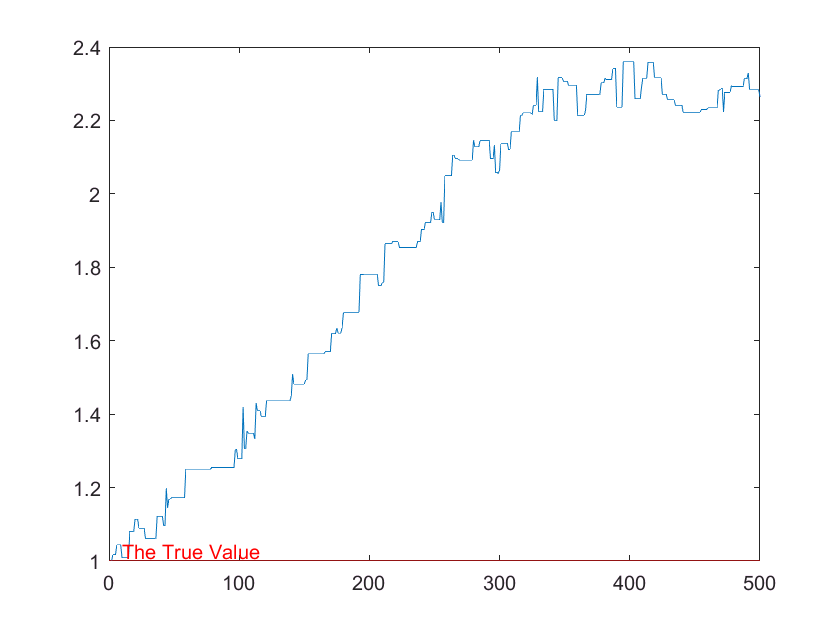

rho_c_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    rho_c_curr=obj{3};
   rho_c_all=[rho_c_all rho_c_curr('rho_c')];
end
plot(rho_c_all)
h =hline(rho_c,'r','The True Value');

Posterior Density of $\rho_c$

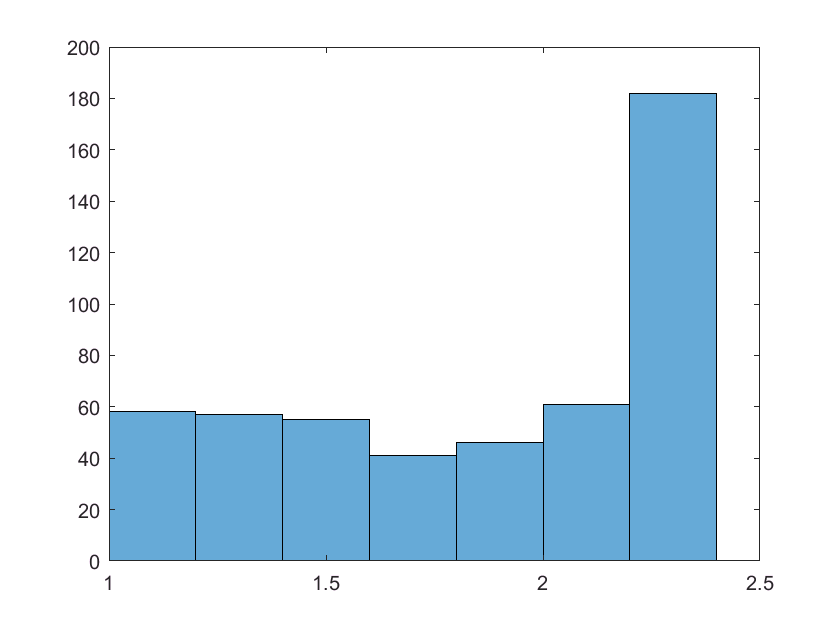

histogram(rho_c_all)

## Spatial DOF ($\nu_c$) of Gaussian Copula

MCMC of $\nu_c$

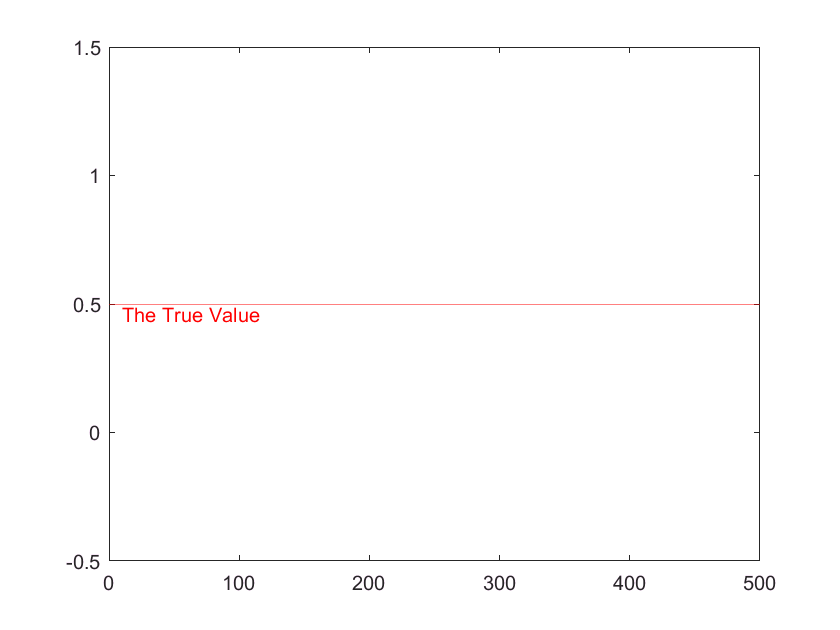

nu_c_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    nu_c_curr=obj{3};
   nu_c_all=[nu_c_all nu_c_curr('nu_c')];
end
plot(nu_c_all)
h =hline(nu_c,'r','The True Value');

Posterior Density of $\nu_c$

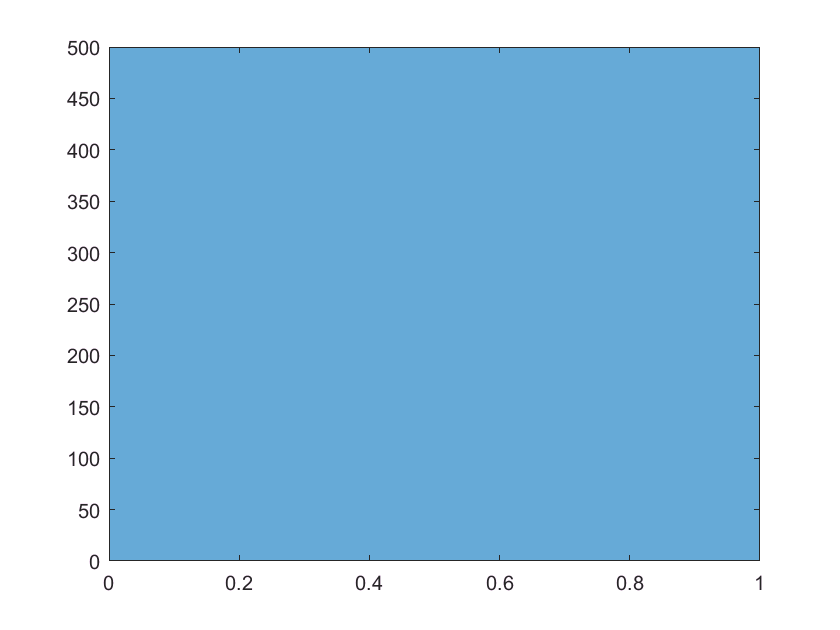

histogram(nu_c_all)

## Spatially Varying Coefficents

MCMC of beta of voxel with signals 

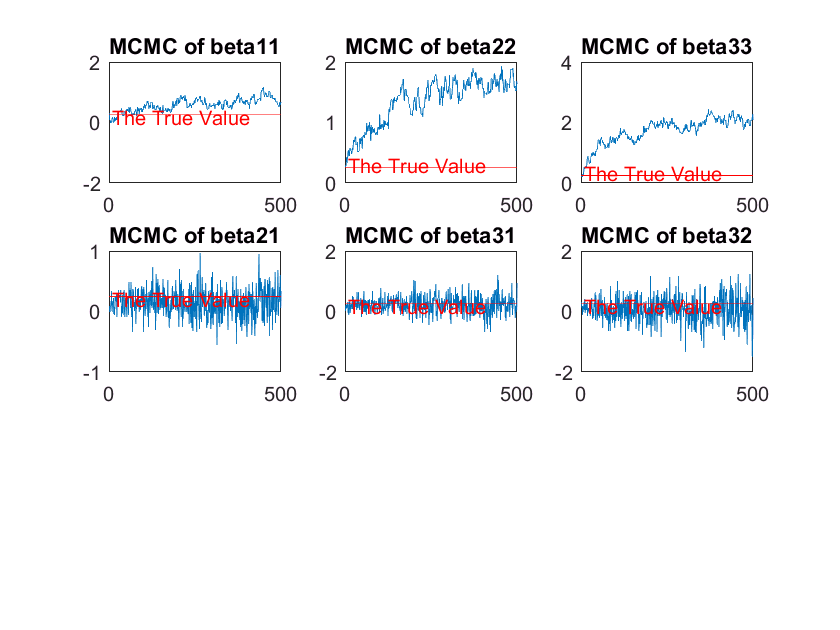

sg=randsample(signal_index,1);

figure
subplot(3,3,1)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta11');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0.25,'r','The True Value');
title('MCMC of beta11')

subplot(3,3,2)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta22');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0.25,'r','The True Value');
title('MCMC of beta22')

subplot(3,3,3)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta33');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0.25,'r','The True Value');
title('MCMC of beta33')

subplot(3,3,4)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta21');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0.25,'r','The True Value');
title('MCMC of beta21')

subplot(3,3,5)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta31');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0.25,'r','The True Value');
title('MCMC of beta31')


subplot(3,3,6)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta32');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0.25,'r','The True Value');
title('MCMC of beta32')

MCMC of beta of voxel with non-signals 

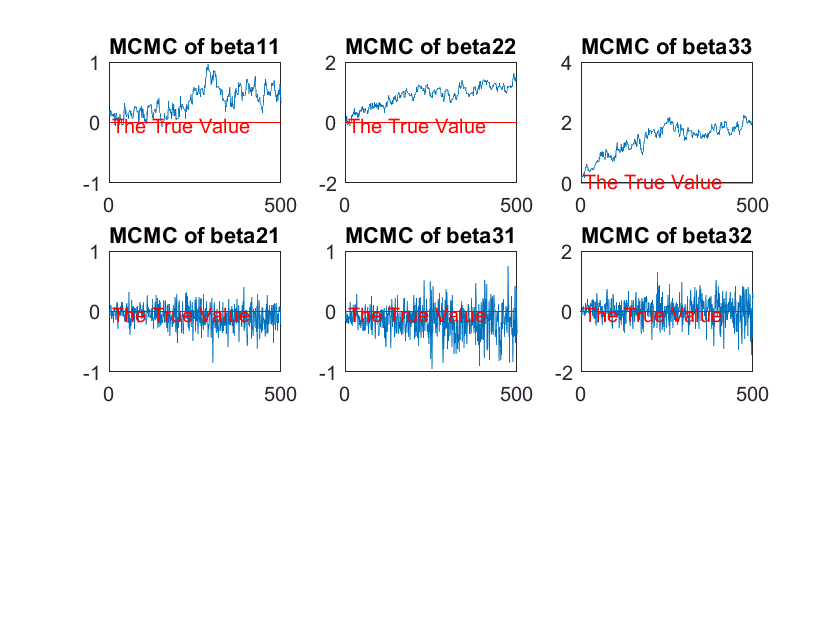

sg=randsample(setdiff(1:ndim,signal_index),1);

figure
subplot(3,3,1)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta11');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','The True Value');
title('MCMC of beta11')

subplot(3,3,2)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta22');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','The True Value');
title('MCMC of beta22')

subplot(3,3,3)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta33');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','The True Value');
title('MCMC of beta33')

subplot(3,3,4)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta21');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','The True Value');
title('MCMC of beta21')

subplot(3,3,5)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta31');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','The True Value');
title('MCMC of beta31')


subplot(3,3,6)  
beta_all=[];
for it=1:iters
    obj=Bookkeeping_MCMC{it};
    beta_curr=obj{4};
    my=beta_curr('beta32');
   beta_all=[beta_all my(sg,1)];
end
plot(beta_all)
h =hline(0,'r','The True Value');
title('MCMC of beta32')